# Roordalab Custom Shack-Hartmann Sensor

Data-reduction pipeline for processing spot-field images

clearvars
close all

A raw Shack-Hartmann spot field image of just a single megapixel contains over a million numbers. The process of reducing this massive amount of data into either a wavefront "surface" sampled over a grid of a few hundred points or a set of polynomial coefficients for a model representation is known as *data reduction*.

measurementFileName = "R25M0006g.tif";  

#### Recommendation

- Scale down for image preprocessing such that either dimension doesn't exceed 256 pixels

#### Assumption

- System aperture is circular

- Microlens array subapertures are square

## 1) Preprocessing 

First preprocess the Shack-Hartmann (SH) spot field image to help isolate contents of interest. If background image is available, alway subtract background. Negative pixel values may appear due to sensor noise; they shall be zeroed. 

% load background and measurement images
bkgd = imread("background.tif");
meas = imread(measurementFileName);
I = uint8(meas - bkgd); % Forcing uint8 zeroes negative values

Rescale image to a quarter the original size image processing

I = imresize(I, 0.25, "AntiAliasing", true);

### 1.1 Stray-light segmentation

Pertains to automatically ignoring pixels contaminate by reflections most likely from cornea. Operator of Roordalab's SH sensor is trained to rotate the glass plate in the light-delivery path to  manually remove visible corneal reflection, so this substep is not applicable.

### 1.2 Thresholding

Implement local threshold operation via top-hat transformation


$$I_2=I- ({I \circ b})$$


where $I$ is background-subtracted spot-field image and $b$ is a 5-by-5 flat structuring element. Gonzalez and Wood's (2002) iterative threshold algorithm is then applied to $I_2$ to achieve local-thresholding effect.

% Top-hat local threshold
Io = GWE.imopen(I, 5);
I2 = I - Io; % top hat (open followed by subtracting from original)
T = GWE.graythresh(I2);

% Apply threshold
[rows, cols] = size(I);
g = false(rows, cols);
g(I2 > T) = true;

Assume hardware is designed such that it's NOT possible for significant straylight to land on pixels outside of system aperture (refer such pixels as* mask pixels*) . Therefore, mask pixels only contains noise and can be ignored (zeroed so assigned to background). 

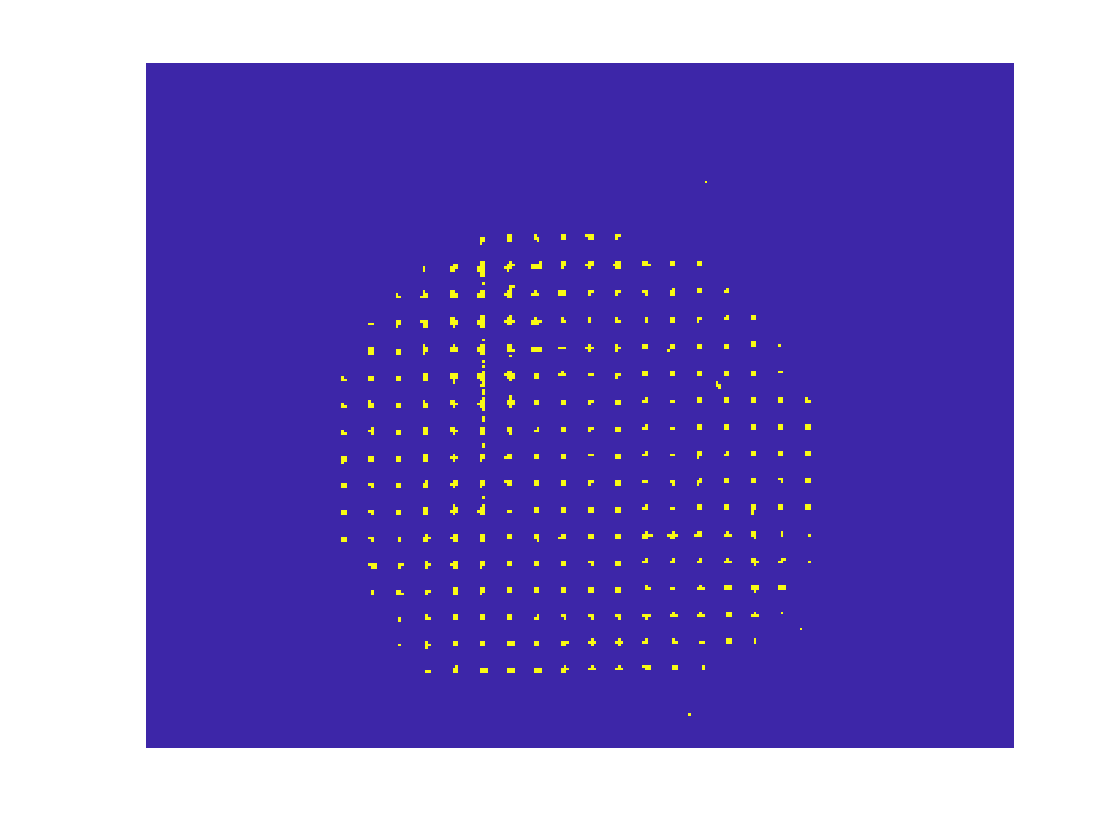

% System aperture "mask"
a = 0.5 * (min(rows, cols) + 1);
[X, Y] = meshgrid(1:cols,1:rows);
R = sqrt((X - 0.5*(cols + 1)).^2 + (Y - 0.5*(rows + 1)).^2);
mask = R > (a-1);

% zero masked pixels
g(mask) = false;
imagesc(g), axis off

## 2) Spot Sorting

Row and column reduction followed by peak analysis. If manual alignment of individual devices

Generate theoretical grid of spots. If a reference image is available (which isn't for Roordalab's sensor), nominal spot locations are based on the reference image. Otherwise, the theoretical grid of spots is used.

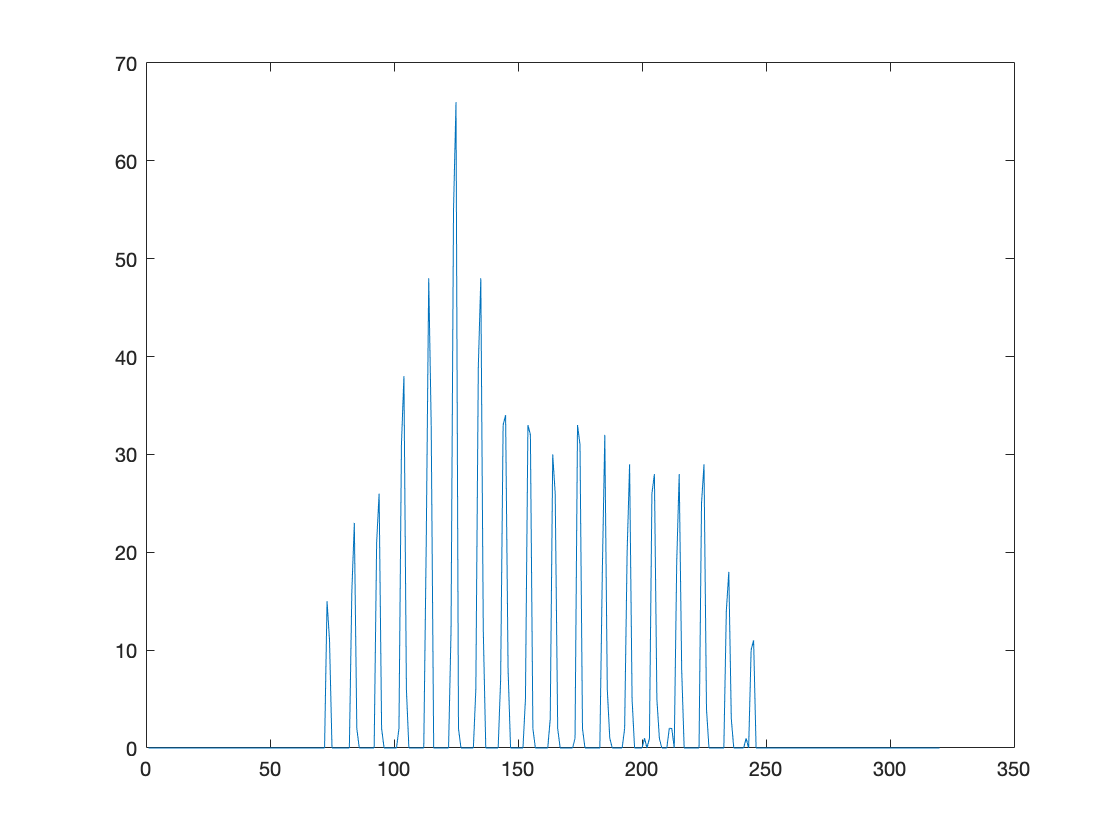

f = sum(g);
plot(f)

% create Shack-Hartmann sensor model
% model = Roorda(bkgd);
% model.process(meas);
% model.show()

Automatically determine eye pupil center 

### 2.1 Pupil Estimation

Convex hull

## 3) Centroiding

## 4) Reconstruction

Wavefront slopes followed by regression

Determine the optimal threshold parameter(s) to isolate pupil in spot-field image

clearvars
close all
sensitivity = 0.3;  

% load images, subtract background, and resize
bkgd = imread("background.tif");
images = {imread("R25M0004g.tif"), imread("R25M0005g.tif"), imread("R25M0006g.tif")}';
binImages = cell(3,1);
for ind = 1:length(images)
    images{ind} = imresize(imsubtract(images{ind}, bkgd), 0.25, "AntiAliasing", true);
    binImages{ind} = imbinarize(images{ind}, "adaptive", "Sensitivity", sensitivity);
end
montage([images, binImages] , "Size", [2 length(images)])